**PROJETO ATD**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% MAIN.M
%
% Este script realiza as seguintes tarefas:
%  1) Cria uma tabela de metadados para os áudios (com informações de diretório,
%     nome, participante, dígito e repetição) e importa os sinais.
%  2) Realiza pré-processamento dos sinais (remoção de silêncio inicial,
%     normalização e ajuste de duração).
%  3) Representa graficamente um exemplo do sinal antes e depois do pré-processamento.
%  4) Extrai 5 características temporais de cada sinal (energia total, desvio padrão,
%     amplitude máxima, zero crossing rate e duração).
%  5) Exibe gráficos (scatter e boxplots) das features agrupados por dígito.
%  6) Remove os sinais de áudio da tabela e salva a estrutura em finalData.mat.
%
% Para executar via terminal:
%   matlab -nosplash -nodesktop -r "run('main.m'); exit;"
%
% Autor: [Seu Nome]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% PARÂMETROS INICIAIS
% Ajuste conforme necessário
baseDir      = '/Users/bernardodireito/Documents/ATD/Projeto_atd/data/40';    % Pasta onde estão os ficheiros .wav
participant  = 40;           % ID do participante conforme os nomes dos arquivos
digitsRange  = 0:9;          % Dígitos de 0 a 9
repetitions  = 0:49;         % 50 gravações de cada dígito
nDigits      = length(digitsRange);
nReps        = length(repetitions);

%% PONTO 1 e 2: CRIAR ESTRUTURA (TABELA) E IMPORTAR SINAIS
% Pré-aloca células e vetores para montar a tabela
nTotal = nDigits * nReps;
diretorio       = cell(nTotal,1);
nomeFicheiro    = cell(nTotal,1);
participanteVec = zeros(nTotal,1);
digito          = zeros(nTotal,1);
repeticao       = zeros(nTotal,1);
audioSignal     = cell(nTotal,1);
fsVal           = zeros(nTotal,1);

% Monta a tabela de metadados e lê cada arquivo
idx = 1;
for d = digitsRange
    for r = repetitions
        % Monta o nome do arquivo: exemplo: 0_40_0.wav
        nomeArq = sprintf('%d_%d_%d.wav', d, participant, r);
        caminho = fullfile(baseDir, nomeArq);

        % Salva os metadados
        diretorio{idx}    = caminho;
        nomeFicheiro{idx} = nomeArq;
        participanteVec(idx) = participant;
        digito(idx)       = d;
        repeticao(idx)    = r;

        % Tenta ler o arquivo de áudio
        try
            [sig, fs] = audioread(caminho);
        catch ME
            warning('Erro ao ler %s: %s', caminho, ME.message);
            sig = []; fs = NaN;
        end

        audioSignal{idx} = sig;
        fsVal(idx)       = fs;

        idx = idx + 1;
    end
end

% Cria a tabela com os metadados e os sinais
T = table(diretorio, nomeFicheiro, participanteVec, digito, repeticao, ...
          audioSignal, fsVal, ...
    'VariableNames', {'Diretorio','NomeFicheiro','Participante','Digito',...
                      'Repeticao','AudioSignal','Fs'});

% Exibe algumas linhas da tabela
disp('--- Tabela com Metadados e Sinais (primeiras 10 linhas) ---');

--- Tabela com Metadados e Sinais (primeiras 10 linhas) ---


disp(T(1:min(10,height(T)), :));

                                   Diretorio                                    NomeFicheiro     Participante    Digito    Repeticao      AudioSignal        Fs  
    _______________________________________________________________________    ______________    ____________    ______    _________    ________________    _____

    {'/Users/bernardodireito/Documents/ATD/Projeto_atd/data/40/0_40_0.wav'}    {'0_40_0.wav'}         40           0           0        {36309×1 double}    48000
    {'/Users/bernardodireito/Documents/ATD/Projeto_atd/data/40/0_40_1.wav'}    {'0_40_1.wav'}         40           0           1        {38165×1 double}    48000
    {'/Users/bernardodireito/Documents/ATD/Projeto_atd/data/40/0_40_2.wav'}    {'0_40_2.wav'}         40         

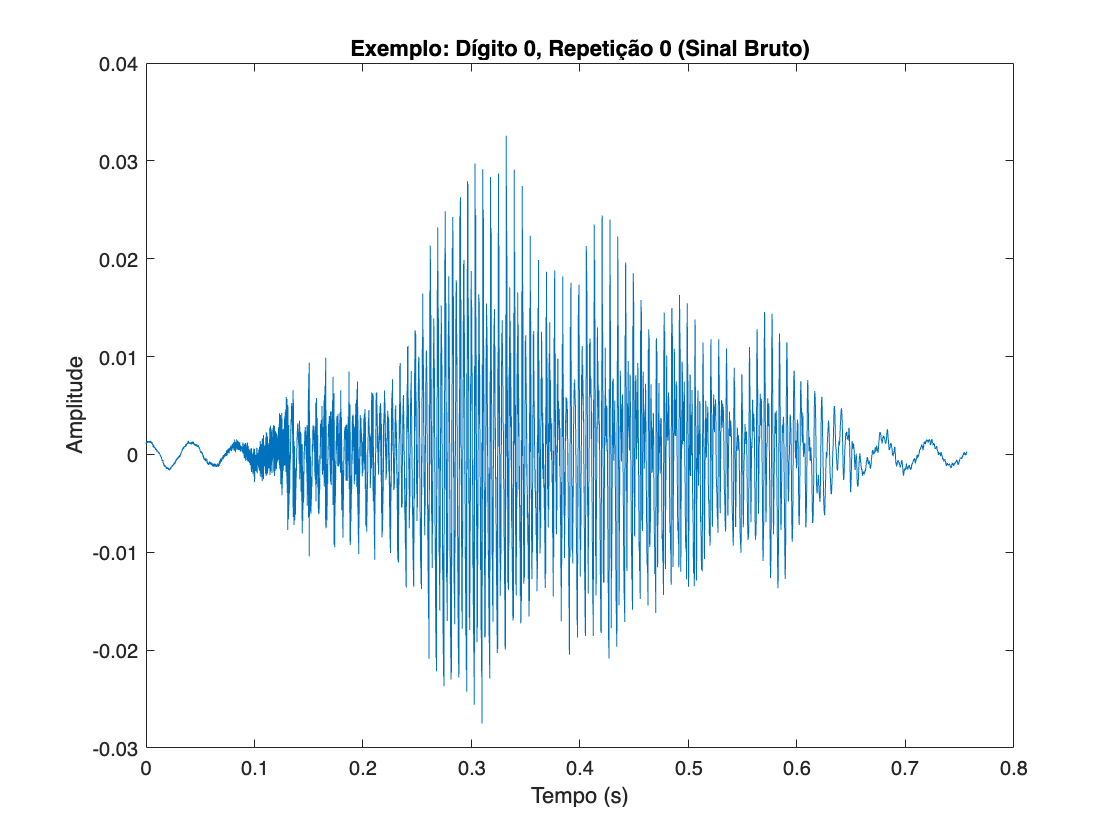


%% PONTO 3: REPRESENTAR GRAFICAMENTE UM EXEMPLO (ANTES DO PRÉ-PROCESSAMENTO)
% Exemplo: dígito 0, repetição 0 (se existir)
idxEx = find(T.Digito==0 & T.Repeticao==0, 1);
if ~isempty(idxEx) && ~isempty(T.AudioSignal{idxEx})
    sigEx = T.AudioSignal{idxEx};
    fsEx  = T.Fs(idxEx);
    tEx   = (0:length(sigEx)-1)/fsEx;

    figure('Name','Exemplo de sinal bruto','NumberTitle','off');
    plot(tEx, sigEx);
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    title('Exemplo: Dígito 0, Repetição 0 (Sinal Bruto)');
else
    warning('Não há arquivo com dígito=0 e repetição=0 ou o sinal está vazio!');
end

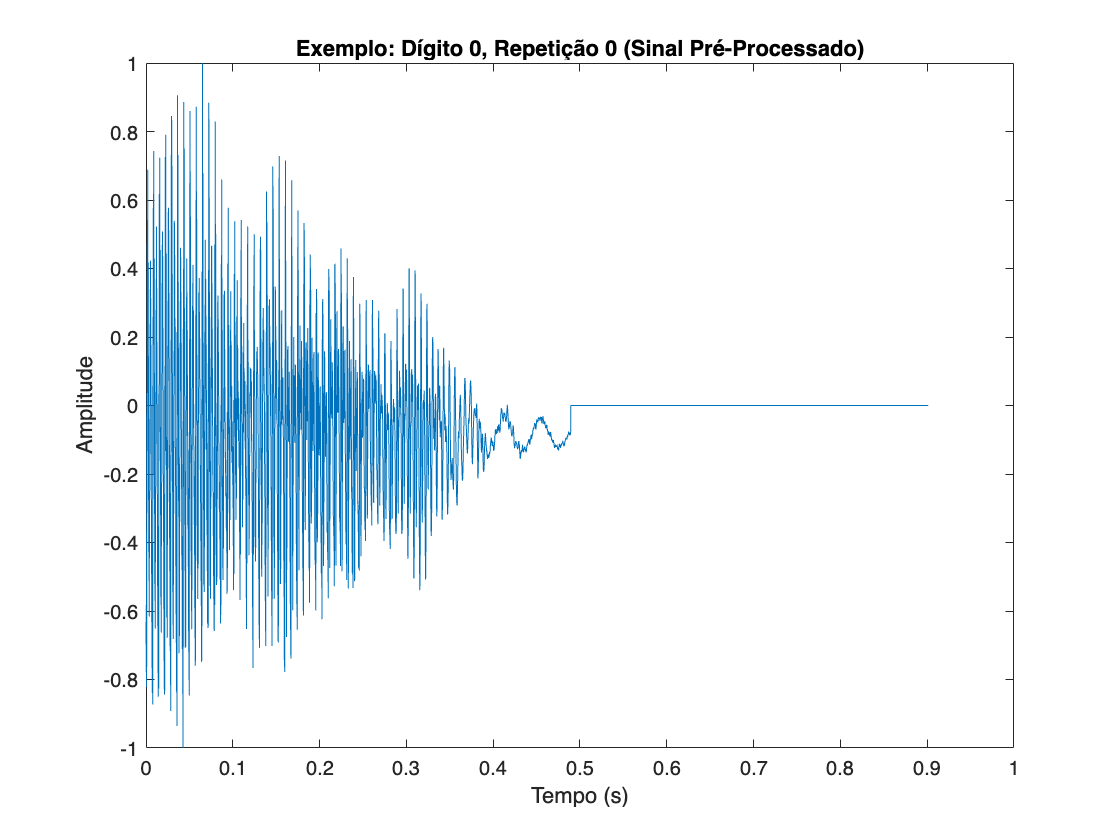


%% PONTO 4: PRÉ-PROCESSAMENTO DOS SINAIS
% 1) Remoção de silêncio inicial (via análise de energia em frames)
% 2) Normalização da amplitude para [-1, 1]
% 3) Ajuste de duração (zero-padding ou truncamento para igualar ao maior sinal)
maxLen = 0;
preprocSignals = cell(nTotal,1);

for i = 1:nTotal
    if ~isempty(T.AudioSignal{i})
        ppSig = preprocessSignal(T.AudioSignal{i}, T.Fs(i));
    else
        ppSig = [];
    end
    preprocSignals{i} = ppSig;
    if length(ppSig) > maxLen
        maxLen = length(ppSig);
    end
end

% Ajusta a duração de todos os sinais para o mesmo tamanho
for i = 1:nTotal
    s = preprocSignals{i};
    if length(s) < maxLen
        s = [s; zeros(maxLen - length(s), 1)];
    else
        s = s(1:maxLen);
    end
    preprocSignals{i} = s;
end

% Adiciona o sinal pré-processado à tabela
T.PreprocSignal = preprocSignals;

%% PONTO 5: REPRESENTAÇÃO GRÁFICA DO EXEMPLO (APÓS PRÉ-PROCESSAMENTO)
if ~isempty(idxEx) && ~isempty(T.PreprocSignal{idxEx})
    sigExPP = T.PreprocSignal{idxEx};
    tExPP   = (0:length(sigExPP)-1)/fsEx;

    figure('Name','Exemplo de sinal pré-processado','NumberTitle','off');
    plot(tExPP, sigExPP);
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    title('Exemplo: Dígito 0, Repetição 0 (Sinal Pré-Processado)');
else
    warning('Não há sinal pré-processado para o exemplo!');
end

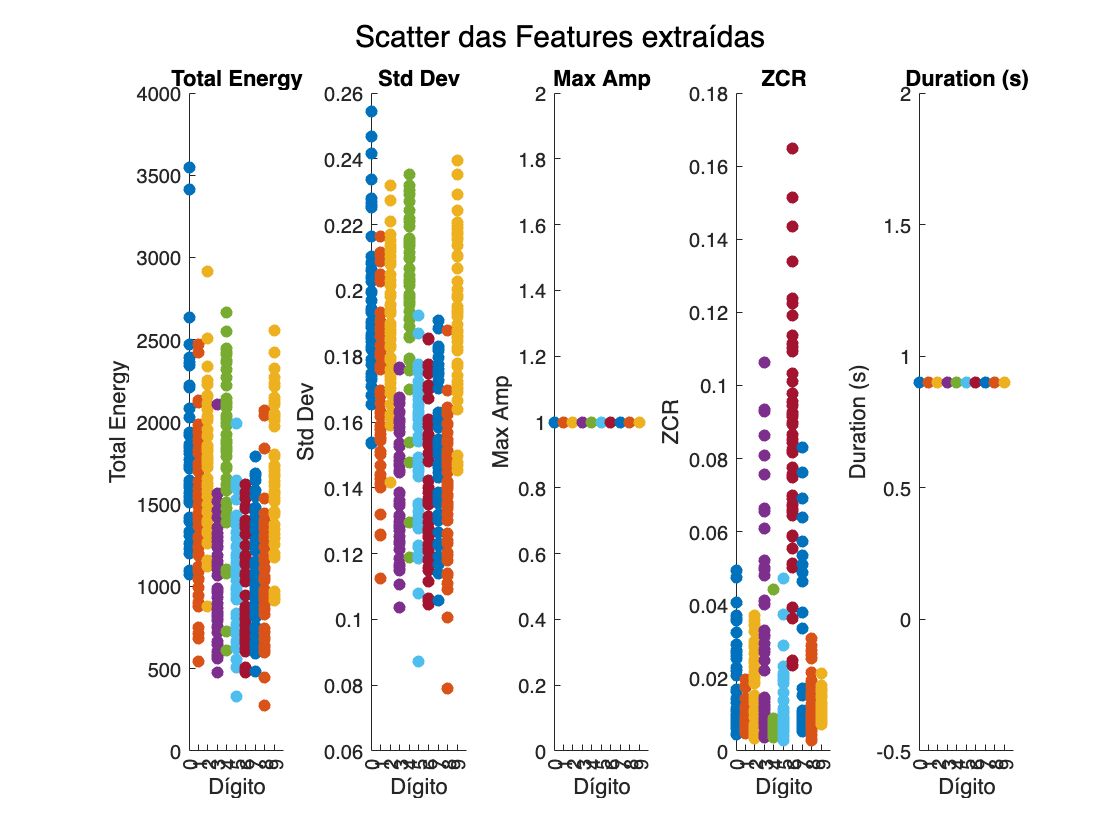


%% PONTO 7: CÁLCULO DAS FEATURES
% Extração de 5 características:
%   1) Energia total
%   2) Desvio padrão
%   3) Amplitude máxima
%   4) Zero Crossing Rate
%   5) Duração (s)
nFeatures = 5;
featuresMatrix = zeros(nTotal, nFeatures);  % Linhas: cada áudio; Colunas: features

for i = 1:nTotal
    if ~isempty(T.PreprocSignal{i})
        feats = computeFeatures(T.PreprocSignal{i}, T.Fs(i));
    else
        feats = zeros(1, nFeatures);
    end
    featuresMatrix(i,:) = feats;
end

% Adiciona as features à tabela
T.TotalEnergy = featuresMatrix(:,1);
T.StdDev      = featuresMatrix(:,2);
T.MaxAmp      = featuresMatrix(:,3);
T.ZCR         = featuresMatrix(:,4);
T.Duration    = featuresMatrix(:,5);

%% PONTO 8: VISUALIZAÇÃO DAS FEATURES
% A) Scatter plots para cada feature versus dígito
figure('Name','Scatter das 5 Features','NumberTitle','off');
featureNames = {'Total Energy','Std Dev','Max Amp','ZCR','Duration (s)'};

for f = 1:nFeatures
    subplot(1,nFeatures,f);
    hold on;
    for d = digitsRange
        idxD = (T.Digito == d);
        scatter(repmat(d,1,sum(idxD)), featuresMatrix(idxD,f), 'filled');
    end
    hold off;
    xlabel('Dígito');
    ylabel(featureNames{f});
    xticks(digitsRange);
    title(featureNames{f});
end
sgtitle('Scatter das Features extraídas');

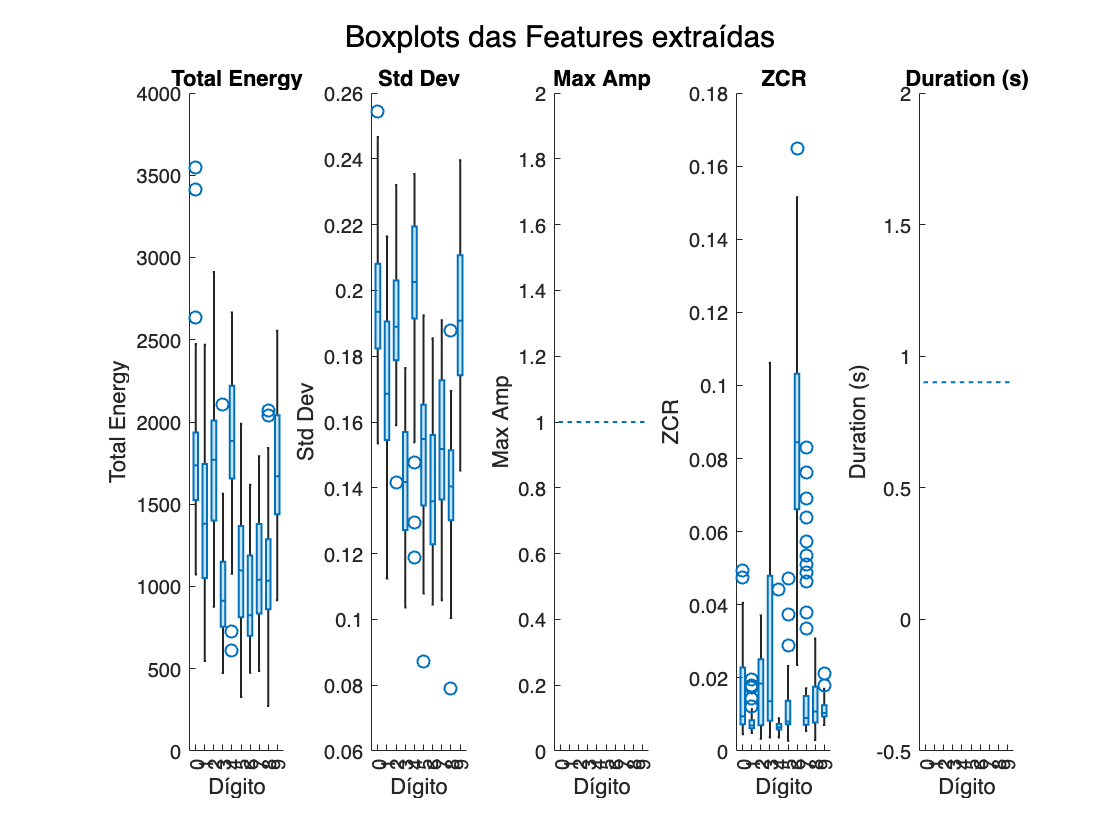


% B) Boxplots para cada feature agrupados por dígito
% Usaremos a função boxchart, disponível em versões recentes do MATLAB.
figure('Name','Boxplots das 5 Features','NumberTitle','off');
for f = 1:nFeatures
    subplot(1,nFeatures,f);
    data = [];
    group= [];
    for d = digitsRange
        idxD = (T.Digito == d);
        data  = [data; featuresMatrix(idxD,f)];
        group = [group; d*ones(sum(idxD),1)];
    end
    % Converte o grupo para variável categórica
    boxchart(categorical(group), data);
    xlabel('Dígito');
    ylabel(featureNames{f});
    title(featureNames{f});
    xticks(categorical(digitsRange));
end
sgtitle('Boxplots das Features extraídas');


%% PONTO 9: REMOÇÃO DOS SINAIS E SALVAMENTO
% Remove as colunas de sinais para economizar espaço
T.AudioSignal    = [];
T.PreprocSignal  = [];
save('finalData.mat', 'T');

disp('--- Fim: Estrutura de dados salva em finalData.mat ---');

--- Fim: Estrutura de dados salva em finalData.mat ---



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       FUNÇÕES AUXILIARES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [ppSig] = preprocessSignal(sig, fs)
    % Pré-processa o sinal:
    %   - Remove silêncio inicial usando energia em frames de 1 ms.
    %   - Normaliza a amplitude para o intervalo [-1, 1].

    frameSizeSec = 0.001;
    frameSamples = round(frameSizeSec * fs);
    numFrames    = floor(length(sig) / frameSamples);
    energy       = getFrameEnergy(sig, frameSamples, numFrames);

    % Define limiar para detectar início do sinal (ajuste se necessário)
    energyThreshold = 0.01;
    startFrame = find(energy > energyThreshold, 1);
    if isempty(startFrame)
        startFrame = 1;
    end
    startSample = (startFrame - 1)*frameSamples + 1;

    % Corta o sinal a partir do início detectado
    ppSig = sig(startSample:end);

    % Normalização para [-1, 1]
    minVal = min(ppSig);
    maxVal = max(ppSig);
    if (maxVal - minVal) < 1e-12
        ppSig = zeros(size(ppSig));
    else
        ppSig = (ppSig - minVal) / (maxVal - minVal);  % [0, 1]
        ppSig = 2*ppSig - 1;                           % [-1, 1]
    end
end

function energyVec = getFrameEnergy(y, frameSamples, numFrames)
    % Calcula a energia (soma dos quadrados) para cada frame
    energyVec = zeros(numFrames, 1);
    for j = 1:numFrames
        frame = y((j-1)*frameSamples + 1 : j*frameSamples);
        energyVec(j) = sum(frame.^2);
    end
end

function feats = computeFeatures(sig, fs)
    % Extrai 5 características do sinal pré-processado:
    % 1) Energia total, 2) Desvio padrão, 3) Amplitude máxima,
    % 4) Zero Crossing Rate, 5) Duração (s)
    feats = zeros(1,5);

    feats(1) = sum(sig.^2);            % Energia total
    feats(2) = std(sig);               % Desvio padrão
    feats(3) = max(abs(sig));          % Amplitude máxima
    feats(4) = zerocrossrate(sig);     % Zero Crossing Rate
    feats(5) = length(sig)/fs;         % Duração em segundos
end

function zcr = zerocrossrate(sig)
    % Calcula a taxa de cruzamento por zero
    s  = sign(sig);
    ds = diff(s);
    zcr = sum(ds ~= 0) / (length(sig)-1);
end